# Digit Recognision ECE 301 Final Project

Alex Pendergast

Heath (002)

## Introduction

This project is the training of a digit recognition model designed to label 28x28 pixel images that contain a number 0 - 9. This project is intended to be tested through and work for [https://www.kaggle.com/c/digit-recognizer/overview](https://www.kaggle.com/c/digit-recognizer/overview)[.](https://www.kaggle.com/c/digit-recognizer/submissions.) All portions of this code is intended to work without any pre-existing functions or imported modules. I am firmly a novice at programming and machine learning so I wanted to start small and work on building a functional program before diving deaper into the field. 

## Data Preperation

Starting by importing the training data given by Kaggle.com. Train_Data which contains all the pixel values for all 42,000 images and Train_Labels which contains the labels for each 28x28 image. 

Train_Num = 42000; % Number of images to train with

Num_Labels = zeros([1, 10]); %generate empty matrix to fill with the amount of the 10 labels
for i = 1:Train_Num
    Label = Train_Labels(i,1);
    Num_Labels(1, (Label+1)) = Num_Labels(1, (Label+1)) + 1;
end
Num_Labels % display the number of each label

Num_Labels =         4132        4684        4177        4351        4072        3795        4137        4401        4063        4188


In a fresh matrix 1x10 matrix it will count the occurences of each label and column (number + 1) for use later.

Train = zeros([1,784]); % generate the matrix which will hold the average image for each number
for k = 1:10
    Train_Temp = zeros([1, 784]);
    for i = 1:Train_Num
        Label = Train_Labels(i,1);
        image = Train_Data(i,:);
        if(Label == (k-1))
            for j = 1:784
                Train_Temp(1,j) = (image(1,j)/(Num_Labels(1,k))) + Train_Temp(1,j); % Equation 1
            end
        end
    end
    Train = cat(3,Train,Train_Temp);   
end
Train(:,:,1) = []; % remove the first empty matrix

For all images with the label "k" the pixel value of each image is normalized and added to the 3D matrix T. This should generate the average value in each pixel for each number with a label. 

### Equation 1 The Average Matrix


$$\mathrm{Let}\;n\;\mathrm{be}\;\mathrm{the}\;\mathrm{number}\;\mathrm{of}\;\mathrm{images}\;\mathrm{with}\;\mathrm{the}\;\mathrm{label}\;m\;\mathrm{and}\;I_m \;\mathrm{be}\;\mathrm{all}\;\mathrm{images}\;\mathrm{with}\;\mathrm{the}\;\mathrm{label}\;m$$



$$A_m =\sum_{i=1}^n \left(\frac{I_m }{n}\right)$$


## Training Data Set Visualization

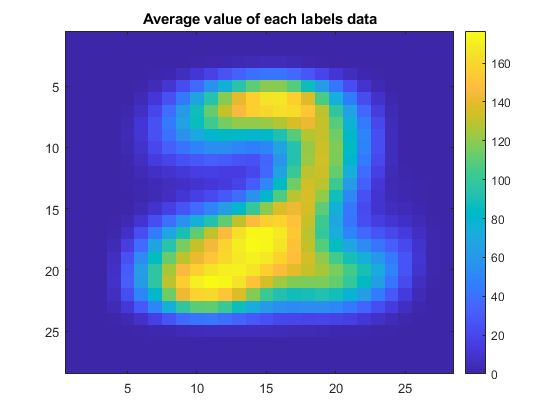

Label = 2; % modify the number to see different average numbers
Train_View = Train(:,:,Label+1);
Train_View = reshape(Train_View,[28,28])';
imagesc(Train_View);
colorbar
title("Average value of each labels data")

This code will show one slice of the 3D matrix at a time corresponding to the value selected for view. The slices are reshaped and transposed to better represent what number is being shown but no data is modified.

## Single Image Test and Visualization

Now that the data is properly prepared the classification of testing data can begin. 

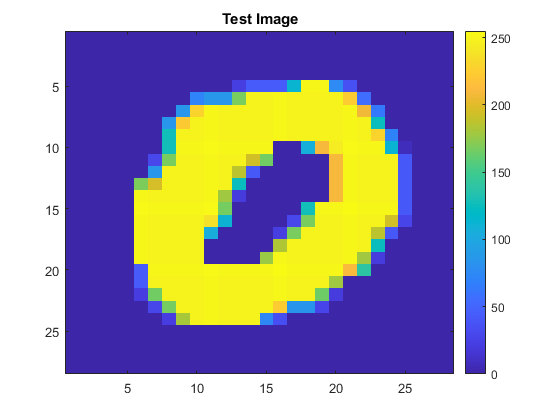

Test_Num = 9566;
Test_View = Test_Data(Test_Num,:);
Test_Case = Test_View;
Test_View = reshape(Test_View,[28,28])';
imagesc(Test_View);
title("Test Image")
colorbar

Score = zeros([1,10]);
for k = 1:10
    Train_View = Train(:,:,k);
    Distance = sqrt((Test_Case-Train_View).^2); % Equation
    Score(1,k) = sum(Distance);
end
Score;
Best_Score = min(Score);
Guess = find(Score==Best_Score) - 1;
Guess = max(Guess);
if(Guess == 1)
    Score = zeros([1,10]);
    for k = 1:10
    Train_View = Train(:,:,k);
        for i = 1:784
            if((Test_Case(1,i) - Train_View(1,i)) < 10)
                Score(1,k) = Score(1,k) + 1;
            end
        end
    end
    Best_Score = max(Score);
    Guess = find(Score==Best_Score) - 1;
    Guess = max(Guess);
    if(Guess == 8)
        Guess = 1;
    end
end
Guess

Guess = 0

This allows you to look at a specific number from the testing set by changing the value of Test_Num. This also sets the image to test individually.

Image classification is done in two parts here, the first by comparing the sum of difference of the image to the training matrix which contains the average of all images with that label. Whichever label has the smallest difference is registered as a prediction for the label. The downside of this approach is over prediction of the label "1" so if the predicted label is "1" a second approach is used to verify the prediction. The label with the image that has the most pixels with a difference of less than 10 is selected as a predicted label. This approach over predicts "8", if that is the case it is ignored but for all other instances it verifies the predicted label. The variable "Guess" is the predicted label for the test image selected.

### Equation 2 Sum of Difference


$$\mathrm{Let}\;A\;\mathrm{be}\;\mathrm{the}\;\mathrm{average}\;\mathrm{matrix}\;\mathrm{and}\;T\;\mathrm{be}\;\mathrm{the}\;\mathrm{matrix}\;\mathrm{of}\;\mathrm{the}\;\mathrm{image}\;\mathrm{being}\;\mathrm{classified}$$



$$S_m =\sum_{i=1}^{784} \sqrt{{\left(A_{1,\;i} -T_{1,i} \right)}^2 }$$


## Set Testing

The exact same testing procedure detailed above can be done on all the 28,000 images in the testing set. 

Test_Labels = zeros([28000,1]);
for j = 1:28000
    Test_Case = Test_Data(j,:);
    for k = 1:10
        Train_View = Train(:,:,k);
        Distance = sqrt((Test_Case-Train_View).^2);
        Score(1,k) = sum(Distance);
    end
    Score;
    Best_Score = min(Score);
    Guess = find(Score==Best_Score) - 1;
    Guess = max(Guess);
    if(Guess == 1)
        Score = zeros([1,10]);
        for k = 1:10
            Train_View = Train(:,:,k);
            for i = 1:784
                if((Test_Case(1,i) - Train_View(1,i)) < 10)
                        Score(1,k) = Score(1,k) + 1;
                end
            end
       end
        Best_Score = max(Score);
        Guess = find(Score==Best_Score) - 1;
        Guess = max(Guess);
        if(Guess == 8)
            Guess = 1;
        end
    end
    Test_Labels(j,1) = Guess(1,1);
end

This code will generate a label for all 28000 test images and generate a matrix with all of the label predictions. This matrix Test_Labels can be uploaded to Kaggle to automatically score attempts with a maximum of 5 allowed per day. 

## Results

With the currently implimented classification models kaggle scores the label predictions at .68685 or 68.685% correct predictions. 

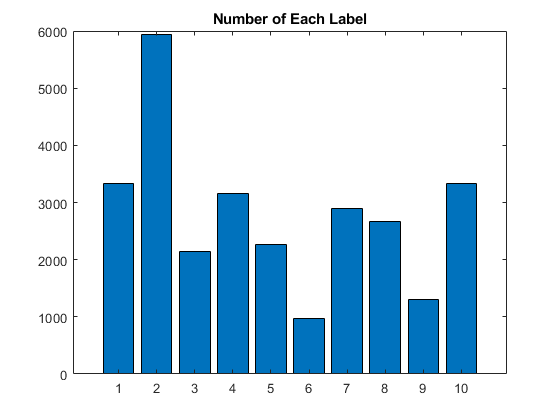

Test_Num = 28000; % count all of the labels to compare
Num_Test_Labels = zeros([1, 10]);
for i = 1:Test_Num
    Label = Test_Labels(i,1);
    Num_Test_Labels(1, (Label+1)) = Num_Test_Labels(1, (Label+1)) + 1;
end
bar(Num_Test_Labels)
title("Number of Each Label")

The bar graph of the number of images with each label shows the preference the model has for predicting the label "1" and its struggle to predict the labels "6" and "9". Assuming there will be approximetly equal amounts of each label similar to the training set.

## Applying existing functions in MATLAB

The manual classification that I formulated to predict a label for images can be entirely replaced with existing functions in MATLAB. To test the upper bounds of my approach I used the K-Nearest Neighbor search function on a modified average image matrix with all images in the testing data. The K-Nearest Neighbor search function compares the testing images to the 10 average numbers and outputs which average number it is closest to automatically. Using this approach the test labels submitted to Kaggle will be 80.79% correct. This function is highly fine tuned so I consider the upper limit of classifying images without a convolutional nueral network to be approximetly 80%.

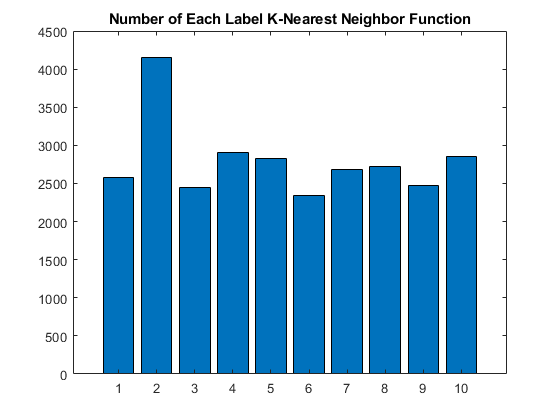

Averages = zeros([10,784]);
for i = 1:1:10
    Averages(i,:) = Train(1,:,i);
end
K_search = knnsearch(Averages, Test_Data); % the one line of code to replace everything I have done
for i = 1:1:28000
    K_search(i,1) = K_search(i,1) - 1; % subtract 1 from the image to get the actual number because matrices start at 1
end
Test_Num = 28000; % count all of the labels to compare amounts of labels appearing
Num_Test_Labels = zeros([1, 10]);
for i = 1:Test_Num
    Label = K_search(i,1);
    Num_Test_Labels(1, (Label+1)) = Num_Test_Labels(1, (Label+1)) + 1;
end
bar(Num_Test_Labels)
title("Number of Each Label K-Nearest Neighbor Function")

A more even bar graph indicates that no number is being over classified except for 1 using the existing function. Compared with the bar graph of my classification attempt numbers are far more even but the over classification of 1s is present in both approaches. 

## Conclusion

In this project I inputed given training data into matlab and used a series of matrix operations to build the average matrix of each label and compare testing images to generate a label. A score of 68.685% correctness was achived with the 28,000 test images, 19231 images had the correct number label.

Starting out with this project I understood almost nothing about even the simplest of machine learning problems and this project has given me a starting point. The restriction of not implementing any pre-existing libraries or functions helped in this case because I understood so little about subject, working through each step has help create the foundation to build and explore the subject further. My knowledge of working with 2d and 3d matrices has also improved by using MATLAB for this project.

Because of the 80.79% correctness of the K-Nearest Neighbor function I know it would be possible to improve the correctness of predictions by tweaking and adding more parameters to test. To simplify testing parameters the next step should be to crop images to only include pixels a value greater than zero. To further retrain the model I could seperate the labeled data and do testing with labels to determine accuracy and modify the model. 

## Citations

P. Bir, “Image Classification with K Nearest Neighbours,” *Medium*, 06-Aug-2019. [Online]. Available: https://medium.com/swlh/image-classification-with-k-nearest-neighbours-51b3a289280. [Accessed: 01-May-2021]. 

“Digit Recognizer: Learn computer vision fundamentals with the famous MNIST data,” *Kaggle*. [Online]. Available: https://www.kaggle.com/c/digit-recognizer/overview. [Accessed: 01-May-2021]. 